# **Moment-Curvature Analysis of a Reinforced Concrete Column Section**

This example demonstrates how to perform moment-curvature analysis on arbitrary OpenSees sections using ``anlys.MomentCurvature``.

Section geometry  : 400 mm x 600 mm rectangular RC column

Concrete cover    : 40 mm (to stirrup outer face)

Longitudinal bars : 10 x D25 (rho_l ~ 1.23 %)

Axial load cases  : 0, -500, -1000, -2000 kN (compression negative)

clear; clc; close all;


opsMAT = OpenSeesMatlab();


  OpenSeesMatlab v3.8.0.1
  OpenSees MEX Interface for MATLAB
  Copyright (c) 2026, By Yexiang Yan

  Type 'help OpenSeesMatlab' in MATLAB for documentation.
  Documentation also available at 
  https://openseesmatlab.readthedocs.io/en/latest/ 



ops = opsMAT.opensees;
opsMC = opsMAT.anlys.MomentCurvature;  % Get MomentCurvature instance
disp(opsMC);

  MomentCurvature with properties:

       secTag: NaN
            P: NaN
          phi: [0×1 double]
            M: [0×1 double]
    FiberData: []
    cyclePath: [0×1 double]
    NMMresult: [1×1 struct]



ops.wipe();
ops.model("basic", "-ndm", 3, "-ndf", 6);

### Define opensees section

% ======================================================================
%  1.  Section geometry (SI: metres)
% ======================================================================
b     = 0.400;   % section width  [m]
h     = 0.600;   % section height [m]
cover = 0.040;   % clear cover to stirrup face [m]
 
% Clear distances from centroid to bar layers
d_top = h/2 - cover;   % distance from centroid to top/bottom bar row
d_mid = 0.0;            % distance from centroid to mid-height bar row
 
% Longitudinal reinforcement
%   Layout  : 3 bars top, 4 bars middle (2 per side), 3 bars bottom
%   Bar dia : D25  (diameter = 25 mm)
db  = 0.025;                 % bar diameter [m]
As1 = pi * db^2 / 4;        % single bar area [m^2]
 
nTop = 3;   % bars in top row
nBot = 3;   % bars in bottom row
nMid = 4;   % bars in middle rows (2 per side face)
 
% Total steel area and reinforcement ratio
As_total = (nTop + nBot + nMid) * As1;
rho_l    = As_total / (b * h);
% Fiber discretisation
nFibY_core  = 16;   % fibres along h in confined core
nFibZ_core  = 10;   % fibres along b in confined core
nFibY_cover = 3;    % fibres in top/bottom cover strips
nFibZ_cover = 10;   % fibres along b in cover strips
nFibY_side  = 10;   % fibres along h in side cover strips
nFibZ_side  = 2;    % fibres in side cover strips

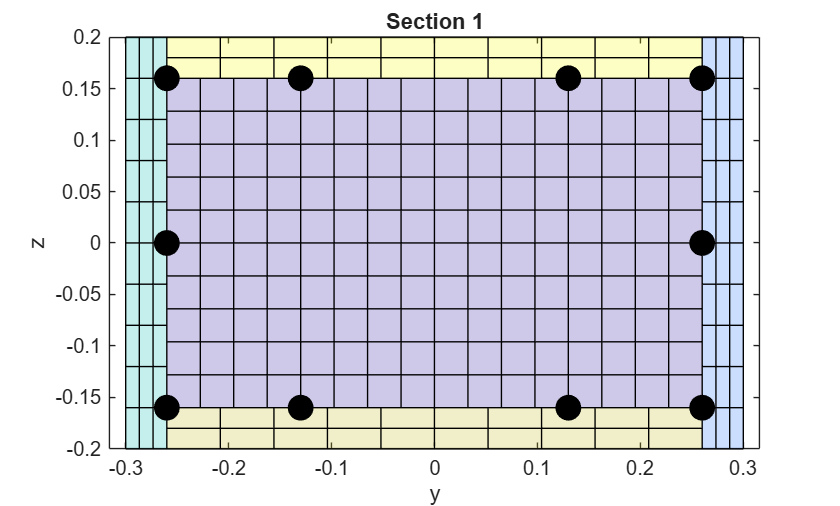

% ======================================================================
%  2.  Material models
% ======================================================================
% Material tags
matConc  = 1;   % confined concrete    (Concrete01 / Mander)
matCover = 2;   % unconfined concrete  (Concrete01)
matSteel = 3;   % reinforcing steel    (Steel02 / Menegotto-Pinto)
 
% --- Confined concrete (Mander model parameters) ---
%   Stirrup: D10 @ 100 mm spacing, 4-leg in both directions
%   (Parameters computed externally from Mander et al. 1988)
fpc_c  = -35.0e6;   % confined peak stress  [Pa]  (negative = compression)
epsc0  = -0.003;   % strain at peak stress
fpcu_c = -28.0e6;   % residual stress  (0.80 * fpc_c)
epscu  = -0.0160;   % ultimate confined strain (Mander formula)
 
ops.uniaxialMaterial('Concrete02', matConc, fpc_c, epsc0, fpcu_c, epscu);
 
% --- Unconfined (cover) concrete ---
fpc_u  = -30.0e6;   % cylinder strength  [Pa]
epsc0u = -0.0020;   % strain at peak (plain concrete)
fpcu_u =  -5.0;      % spalls at ultimate (brittle)
epscuu = -0.0040;   % ultimate strain of cover
 
ops.uniaxialMaterial('Concrete02', matCover, fpc_u, epsc0u, fpcu_u, epscuu);
 
% --- Reinforcing steel (Menegotto-Pinto / Steel02) ---
Fy  = 400.0e6;   % yield strength     [Pa]
Es  = 200.0e9;   % elastic modulus    [Pa]
b_s = 0.01;     % strain-hardening ratio (post-yield slope / Es)
%   Recommended Menegotto-Pinto constants (Filippou et al. 1983):
R0  = 18;  cR1 = 0.925;  cR2 = 0.15;
 
ops.uniaxialMaterial('Steel02', matSteel+10, Fy, Es, b_s, R0, cR1, cR2);
ops.uniaxialMaterial('MinMax', matSteel, matSteel+10, '-min', -0.15, '-max', 0.15);
 
eps_y = Fy / Es;   % yield strain (used later for yield-point search)

% ======================================================================
%  3.  Fiber section  (secTag = 1, bending about local y-axis)
% ======================================================================
%
%  Coordinate convention (OpenSees zeroLengthSection, local axes):
%    y : horizontal (width b)
%    z : vertical   (height h)
%  Bending about y-axis  => M acts about the z-direction on plan,
%  but OpenSees DOF 5 = My.
%
%  Patch corners: (z_min, y_min, z_max, y_max)  [for 'rect' patch]
%
%         z (height)
%         ^
%         |       b = 0.40 m
%    _____|_______________________
%   |     |       cover          |   <- z = +h/2
%   |     |  _______________     |
%   | cov |  |             | cov|
%   |     |  |  confined   |    |   <- core region
%   |     |  |   concrete  |    |
%   |     |  |_____________|    |
%   |     |       cover         |   <- z = -h/2
%   |_____|_____________________|-----> y (width)
%
secTag = 1;

opsMAT.pre.setSectionGeometryRecorder(true);
ops.section('Fiber', secTag, "-GJ", 1E12);
 
% Core concrete patch (confined)
ops.patch('rect', matConc, nFibY_core, nFibZ_core, ...
    -(h/2 - cover), -(b/2 - cover), ...   % z_min, y_min
     (h/2 - cover),  (b/2 - cover));      % z_max, y_max
 
% Cover patches (unconfined) - top strip
ops.patch('rect', matCover, nFibY_cover, nFibZ_cover, ...
     (h/2 - cover), -b/2, h/2, b/2);
 
% Cover patches - bottom strip
ops.patch('rect', matCover, nFibY_cover, nFibZ_cover, ...
    -h/2, -b/2, -(h/2 - cover), b/2);
 
% Cover patches - left side strip
ops.patch('rect', matCover, nFibY_side, nFibZ_side, ...
    -(h/2 - cover), -b/2, (h/2 - cover), -(b/2 - cover));
 
% Cover patches - right side strip
ops.patch('rect', matCover, nFibY_side, nFibZ_side, ...
    -(h/2 - cover), (b/2 - cover), (h/2 - cover), b/2);
 
% Reinforcement layers (layer 'straight': matTag, nBars, As, z1,y1, z2,y2)
%   Top row    (z = +d_top)
ops.layer('straight', matSteel, nTop, As1, ...
     d_top, -(b/2 - cover), d_top, (b/2 - cover));
 
%   Bottom row (z = -d_top)
ops.layer('straight', matSteel, nBot, As1, ...
    -d_top, -(b/2 - cover), -d_top, (b/2 - cover));
 
%   Middle rows on left face
ops.layer('straight', matSteel, 2, As1, ...
    -(h/4 - cover/2), -(b/2 - cover), (h/4 - cover/2), -(b/2 - cover));
 
%   Middle rows on right face
ops.layer('straight', matSteel, 2, As1, ...
    -(h/4 - cover/2), (b/2 - cover), (h/4 - cover/2), (b/2 - cover));
opsMAT.pre.plotSection(secTag);

opsMAT.pre.setSectionGeometryRecorder(false);

### Monotonic M-phi for four axial load levels

N_cases  = [0, -500e3, -1000e3, -2000e3];   % [N]
N_labels = {'N = 0', 'N = -500 kN', 'N = -1000 kN', 'N = -2000 kN'};
colors   = {'#1f77b4','#ff7f0e','#2ca02c','#d62728'};
 
maxPhi  = 0.15;   % maximum curvature to push to  [1/m]
incrPhi = 5e-4;   % base curvature increment       [1/m]
 
mc_list = cell(numel(N_cases), 1);
 
% fprintf('\n--- Monotonic analysis ---\n');
for k = 1:numel(N_cases)
    fprintf('  Case %d: %s\n', k, N_labels{k});
    mc_list{k} = opsMC.new(secTag, N_cases(k));
    mc_list{k}.analyze( ...
        'axis',           'y',   ...
        'maxPhi',         maxPhi, ...
        'incrPhi',        incrPhi, ...
        'limitPeakRatio', 0.80,  ...
        'smartAnalyze',   true);
end

  Case 1: N = 0


MomentCurvature: analysis complete.


  Case 2: N = -500 kN


MomentCurvature: analysis complete.


  Case 3: N = -1000 kN


MomentCurvature: analysis complete.


  Case 4: N = -2000 kN


MomentCurvature: analysis complete.


Plot M-phi for all axial load levels

fig1 = figure('Position',[60 60 860 520], 'Color','w');
ax1  = axes(fig1);
hold(ax1, 'on');
for k = 1:numel(N_cases)
    [phi_k, M_k] = mc_list{k}.getMPhi();
    plot(ax1, phi_k, M_k/1e3, '-', ...
        'Color', colors{k}, 'LineWidth', 1.8, 'DisplayName', N_labels{k});
end
hold(ax1, 'off');
xlabel(ax1, 'Curvature  \phi  [1/m]',  'FontSize',14);
ylabel(ax1, 'Moment  M  [kN\cdotm]',   'FontSize',14);
title(ax1,  '400\times600 RC Column — Moment-Curvature', 'FontSize',15);
legend(ax1, 'Location','northeast', 'FontSize',12);
grid(ax1, 'on'); box(ax1, 'on');

Yield and ultimate curvature for each case:

fprintf('\n--- Limit-state identification ---\n');


--- Limit-state identification ---


fprintf('%-18s  %-10s %-12s  %-10s %-12s  %-8s\n', ...
    'Case', 'phi_y[1/m]', 'My[kN.m]', 'phi_u[1/m]', 'Mu[kN.m]', 'mu_phi');

Case                phi_y[1/m] My[kN.m]      phi_u[1/m] Mu[kN.m]      mu_phi  


 
results = struct();
for k = 1:numel(N_cases)
    mc = mc_list{k};
 
    % --- Yield point: first yielding of tension steel (matTag=3, eps = +eps_y) ---
    [phi_y, M_y] = mc.getLimitState('matTag', matSteel, 'threshold', eps_y);
 
    % --- Ultimate point: cover concrete crushing (matTag=2, eps = epscuu) ---
    [phi_u1, M_u1] = mc.getLimitState('matTag', matCover, 'threshold', epscuu);

    % --- Ultimate point: confined concrete crushing (matTag=3, eps = epscu) ---
    [phi_u2, M_u2] = mc.getLimitState('matTag', matConc, 'threshold', epscu);
 
    % --- Ultimate point: 20 % post-peak drop ---
    [phi_u3, M_u3] = mc.getLimitState('peakDrop', 0.20);
 
    % Take the more critical (smaller) ultimate curvature
    if phi_u2 < phi_u3
        phi_u = phi_u2; M_u = M_u2;
        ult_ctrl = 'crushing';
    else
        phi_u = phi_u3; M_u = M_u3;
        ult_ctrl = 'peak-drop';
    end
 
    mu_phi = phi_u / phi_y;   % curvature ductility
 
    results(k).N     = N_cases(k);
    results(k).phi_y = phi_y;
    results(k).M_y   = M_y;
    results(k).phi_u = phi_u;
    results(k).M_u   = M_u;
    results(k).mu    = mu_phi;
    results(k).ctrl  = ult_ctrl;
 
    fprintf('%-18s  %10.4f %12.1f  %10.4f %12.1f  %8.2f  [%s]\n', ...
        N_labels{k}, phi_y, M_y/1e3, phi_u, M_u/1e3, mu_phi, ult_ctrl);
end

N = 0                   0.0090        325.0      0.1500        362.6     16.67  [peak-drop]


N = -500 kN             0.0095        385.2      0.1500        412.7     15.79  [peak-drop]


N = -1000 kN            0.0105        446.3      0.1500        448.7     14.29  [peak-drop]


N = -2000 kN            0.0125        543.1      0.1215        470.6      9.72  [crushing]


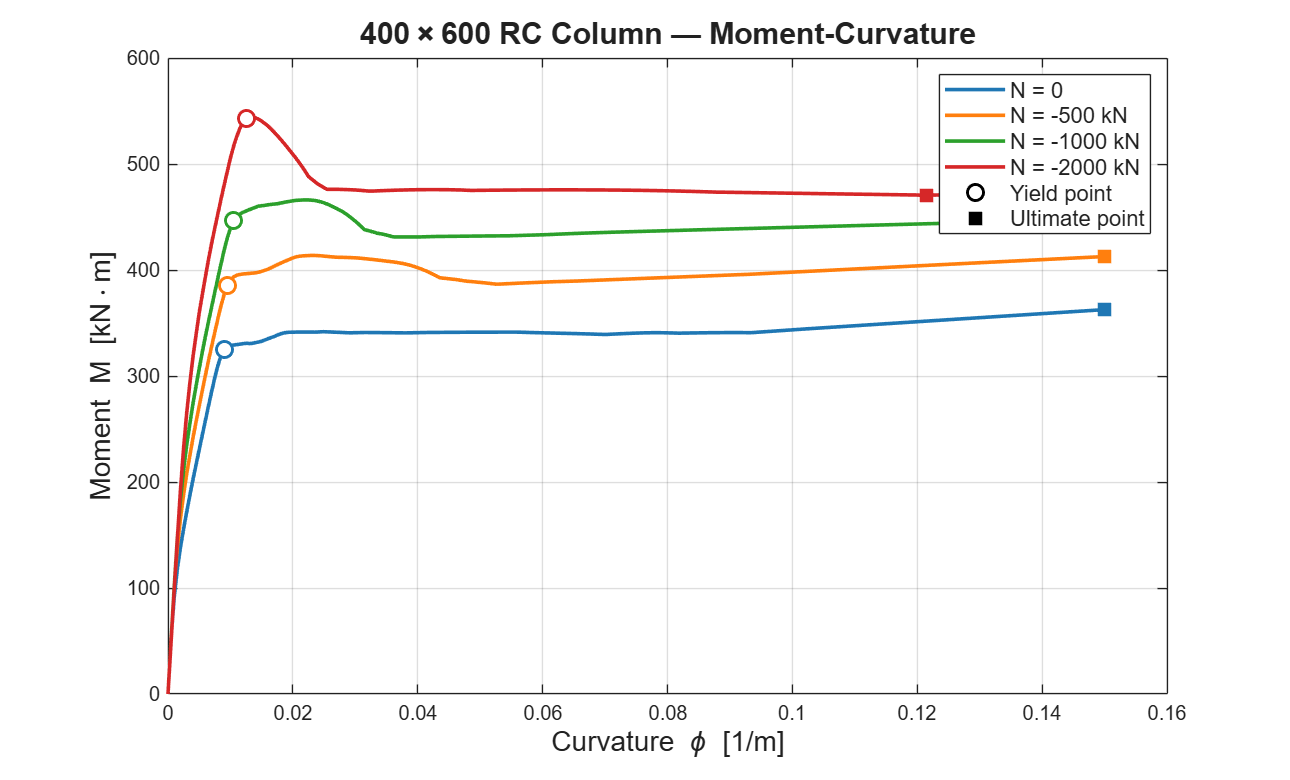

 
% Mark yield and ultimate on the M-phi plot
hold(ax1, 'on');
for k = 1:numel(N_cases)
    r = results(k);
    plot(ax1, r.phi_y, r.M_y/1e3, 'o', ...
        'MarkerSize',8, 'MarkerEdgeColor', colors{k}, ...
        'MarkerFaceColor','w', 'LineWidth',1.5, 'HandleVisibility','off');
    plot(ax1, r.phi_u, r.M_u/1e3, 's', ...
        'MarkerSize',8, 'MarkerEdgeColor', colors{k}, ...
        'MarkerFaceColor', colors{k}, 'HandleVisibility','off');
end
% Legend entries for markers only (dummy plots)
plot(ax1, nan, nan, 'ko', 'MarkerSize',8, 'MarkerFaceColor','w', ...
    'LineWidth',1.5, 'DisplayName','Yield point');
plot(ax1, nan, nan, 'ks', 'MarkerSize',8, 'MarkerFaceColor','k', ...
    'DisplayName','Ultimate point');
legend(ax1, 'Location','northeast', 'FontSize',11);
hold(ax1, 'off');

Bilinear approximation for each axial load case

fig2 = figure('Position',[50, 50, 860, 1000], 'Color','w');
for k = 1:numel(N_cases)
    mc = mc_list{k};
    r  = results(k);
    ax_k = subplot(numel(N_cases), 1, k, 'Parent', fig2);
 
    [phi_eq, M_eq] = mc.bilinearize( ...
        r.phi_y, r.M_y, r.phi_u, 'plot', true, 'ax', ax_k);
    results(k).phi_eq = phi_eq;
    results(k).M_eq   = M_eq;
    title(ax_k, N_labels{k}, 'FontSize',11);
    ax_k.XLabel.FontSize = 10;
    ax_k.YLabel.FontSize = 10;
 
    fprintf('%-18s  %10.4f %12.1f\n', N_labels{k}, phi_eq, M_eq/1e3);
end

N = 0                   0.0096        347.5
N = -500 kN             0.0100        403.8
N = -1000 kN            0.0105        447.1
N = -2000 kN            0.0113        489.9


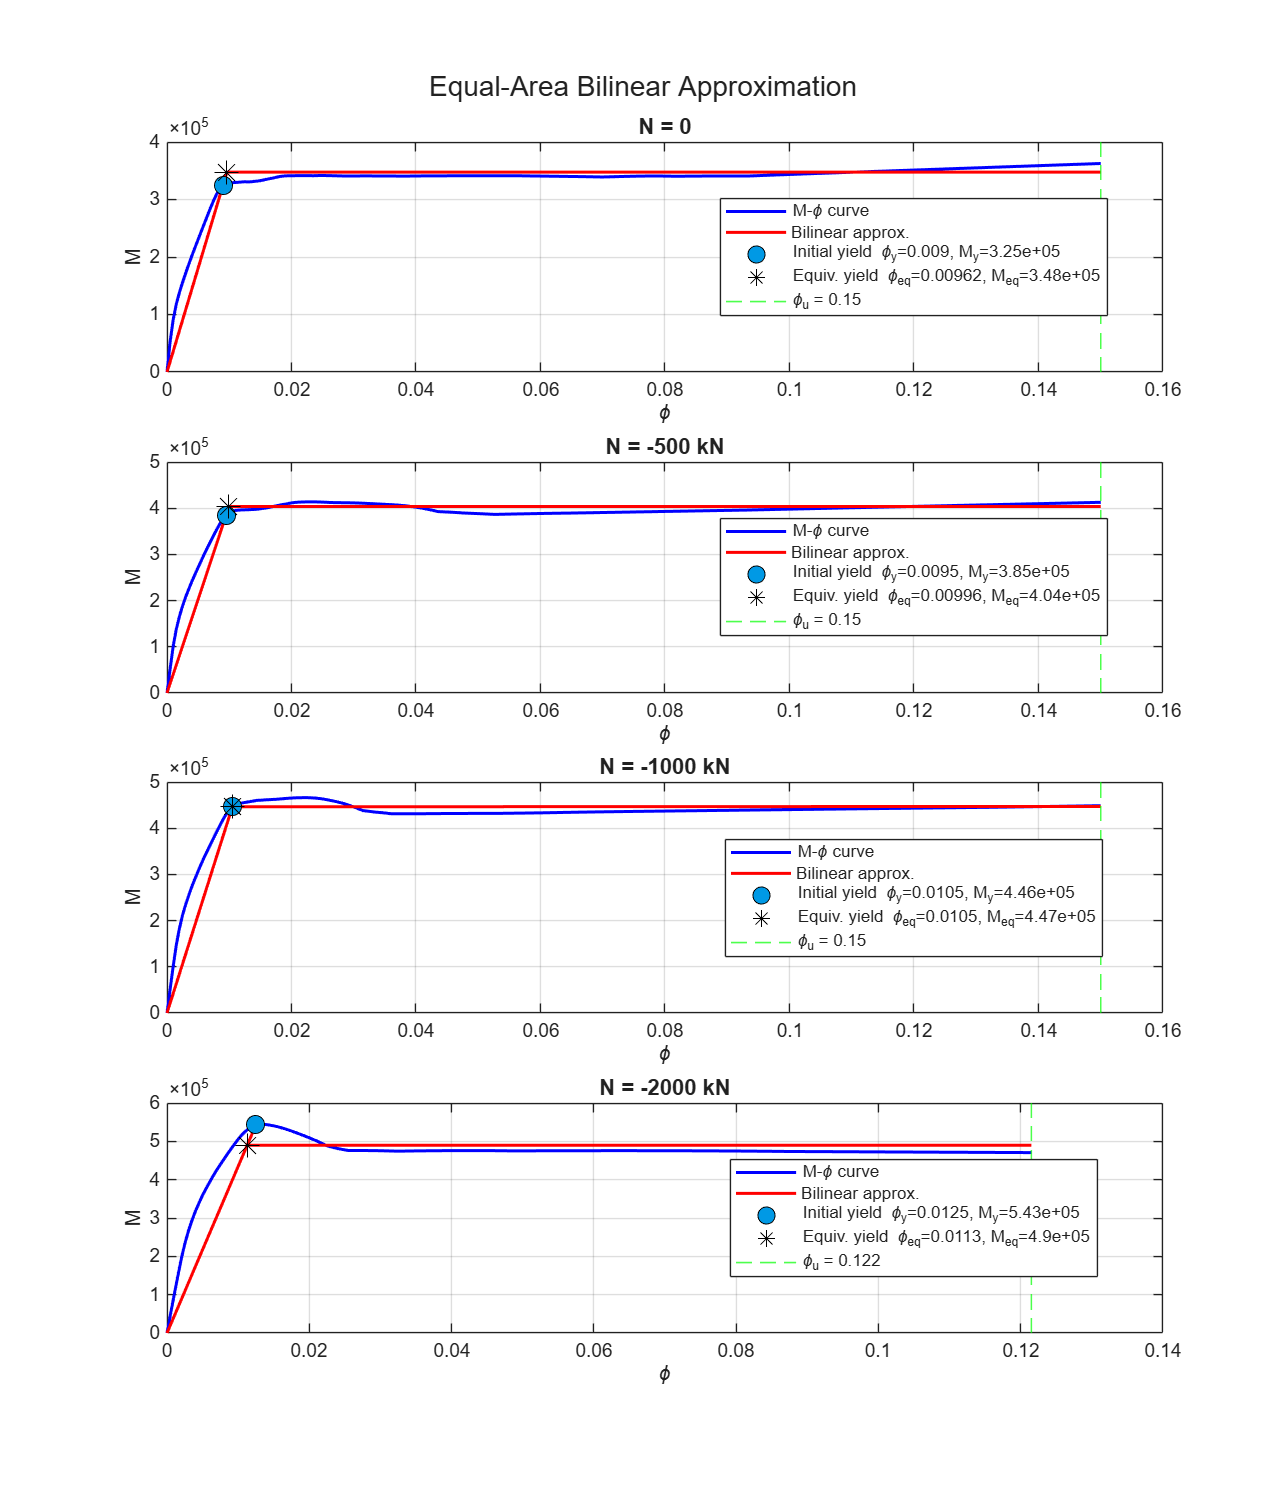

sgtitle(fig2, 'Equal-Area Bilinear Approximation', 'FontSize',14);

Plot stress-strain history of fiber points:

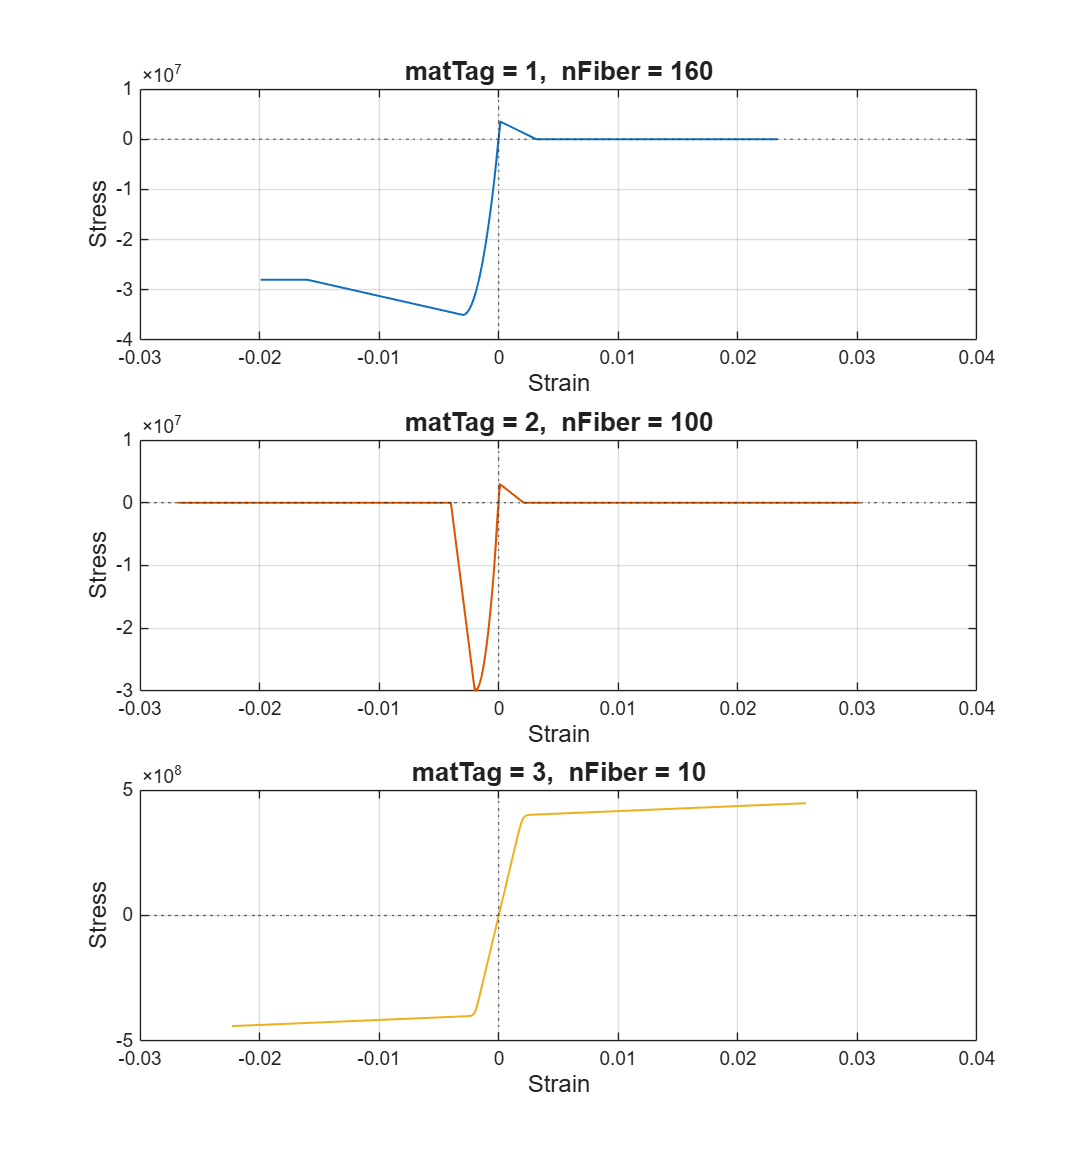

mc_list{4}.plotFiberResponses();

Ductility summary bar chart

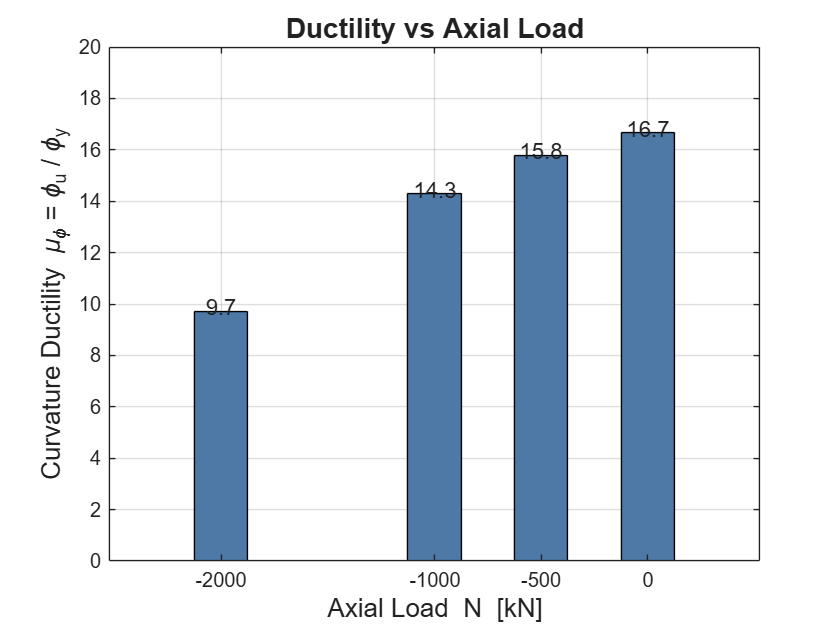

fig3 = figure('Position',[940 60 560 420], 'Color','w');
ax3  = axes(fig3);
mu_vals = [results.mu];
N_kN    = [results.N] / 1e3;
bar(ax3, N_kN, mu_vals, 0.5, 'FaceColor','#4e79a7', 'EdgeColor','k');
xlabel(ax3, 'Axial Load  N  [kN]', 'FontSize',13);
ylabel(ax3, 'Curvature Ductility  \mu_\phi = \phi_u / \phi_y', 'FontSize',13);
title(ax3, 'Ductility vs Axial Load', 'FontSize',14);
text(N_kN, mu_vals + 0.15, arrayfun(@(x) sprintf('%.1f',x), mu_vals, ...
    'UniformOutput',false), 'HorizontalAlignment','center', 'FontSize',11);
ylim(ax3, [0, max(mu_vals)*1.2]);
grid(ax3, 'on'); box(ax3, 'on');

### N-My-Mz interaction surface (strong + weak axis)

% Use a fresh object (P handled internally by buildNMM)
mc_nmm = opsMC.new(secTag, 0);
mc_nmm.buildNMM( ...
    'NList',          linspace(-2400e3, 0, 21)', ...
    'axis1',          'y', ...
    'axis2',          'z', ...
    "capacityMode",   "strain", ...
    "matTag",         matSteel, ...
    "threshold",      eps_y, ...
    'phiMax',         maxPhi,  ...
    'incrPhi',        incrPhi, ...
    'nTheta',         36,      ...
    'limitPeakRatio', 0.80,    ...
    'smartAnalyze',   true,    ...
    'useParallel',    false);

buildNMM: capacityMode=strain,  21 levels x 2 = 42 analyses.
  N = -2.400e+06  (1/21)
  N = -2.280e+06  (2/21)
  N = -2.160e+06  (3/21)
  N = -2.040e+06  (4/21)
  N = -1.920e+06  (5/21)
  N = -1.800e+06  (6/21)
  N = -1.680e+06  (7/21)
  N = -1.560e+06  (8/21)
  N = -1.440e+06  (9/21)
  N = -1.320e+06  (10/21)
  N = -1.200e+06  (11/21)
  N = -1.080e+06  (12/21)
  N = -9.600e+05  (13/21)
  N = -8.400e+05  (14/21)
  N = -7.200e+05  (15/21)
  N = -6.000e+05  (16/21)
  N = -4.800e+05  (17/21)
  N = -3.600e+05  (18/21)
  N = -2.400e+05  (19/21)
  N = -1.200e+05  (20/21)
  N = +0.000e+00  (21/21)
buildNMM: done.  (42 OpenSees analyses)


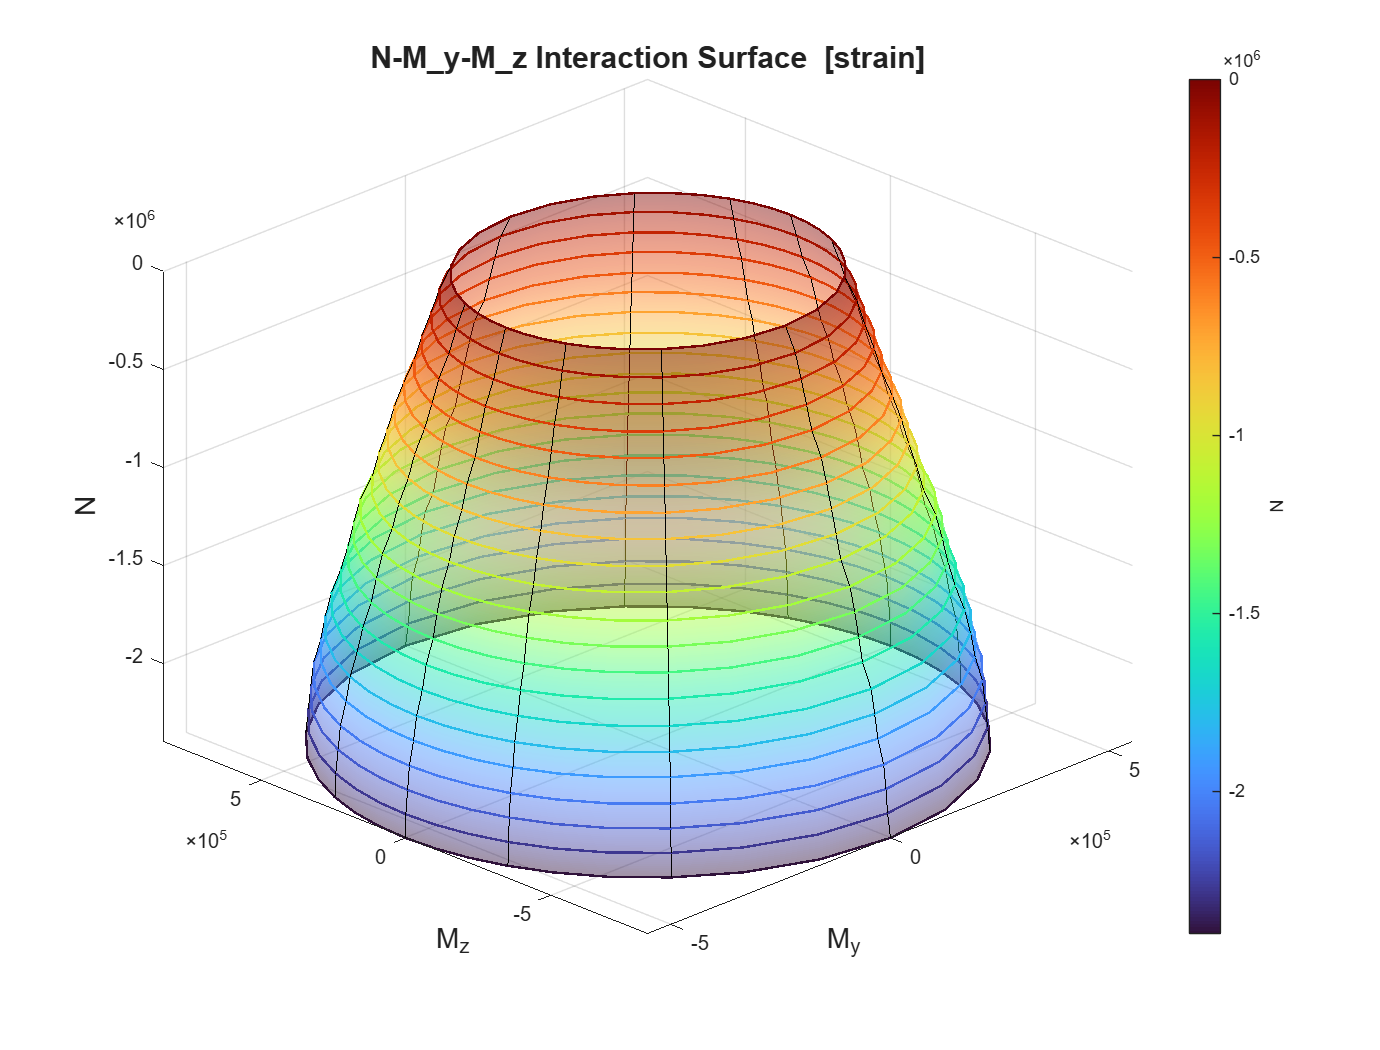

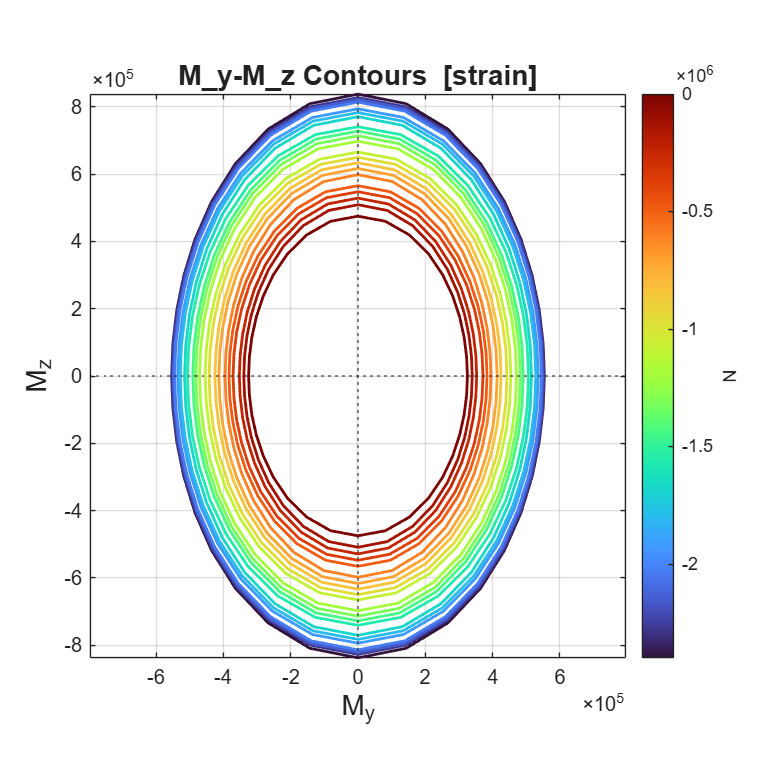

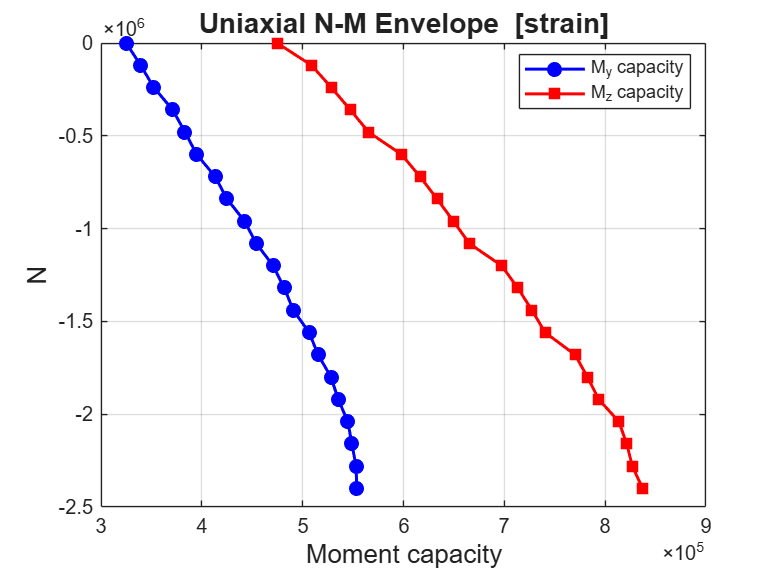

mc_nmm.plotNMM('normalize', false, 'alpha', 0.45, 'colormap', 'turbo');

### Cyclic analysis at N = -1000 kN

N_cyc  = -1000e3;
mc_cyc = opsMC.new(secTag, N_cyc);

% Target drift: phi_u at N=-1000 kN, 12 amplitude levels, 2 repeats each
phi_u_ref = results(3).phi_u;   % index 3 = N=-1000 kN case
mc_cyc.setCyclePath(phi_u_ref, 'nCycle', 12, 'nHold', 2);

mc_cyc.analyze( ...
    'axis',           'y',          ...
    'maxPhi',         phi_u_ref,    ...
    'incrPhi',        incrPhi,      ...
    'limitPeakRatio', 0.80,         ...
    'cycleAnalyze',   true,         ...
    'smartAnalyze',   true);

MomentCurvature: analysis complete.


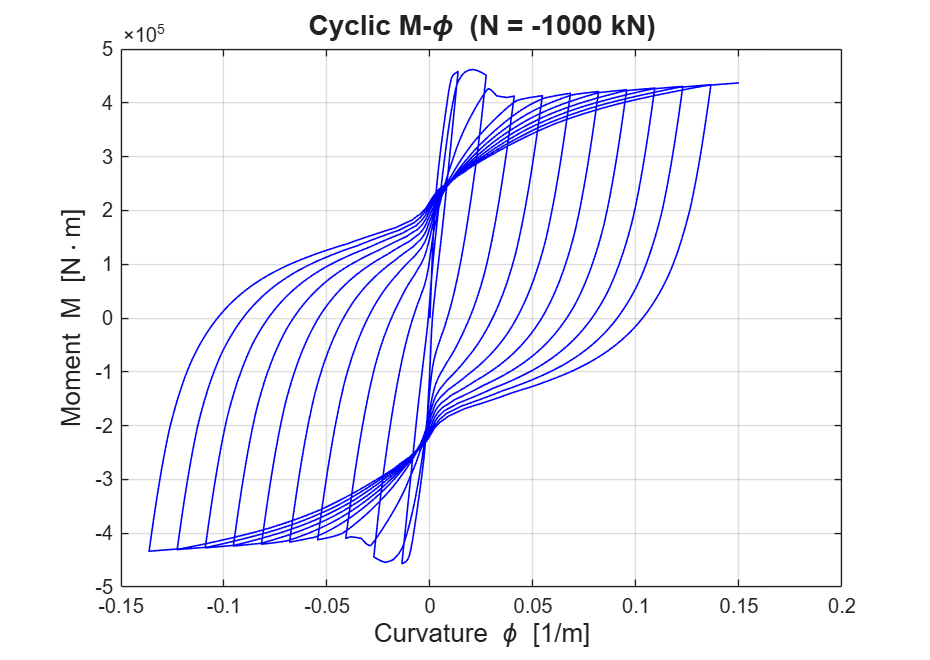


% Plot cyclic M-phi
fig4 = figure('Position',[940 540 620 440], 'Color','w');
ax4  = axes(fig4);
mc_cyc.plotMPhi(ax4);
title(ax4, sprintf('Cyclic M-\\phi  (N = %.0f kN)', N_cyc/1e3), 'FontSize',14);
xlabel(ax4, 'Curvature  \phi  [1/m]', 'FontSize',13);
ylabel(ax4, 'Moment  M  [N\cdotm]',   'FontSize',13);

Fiber stress-strain histories (N = -1000 kN, monotonic)

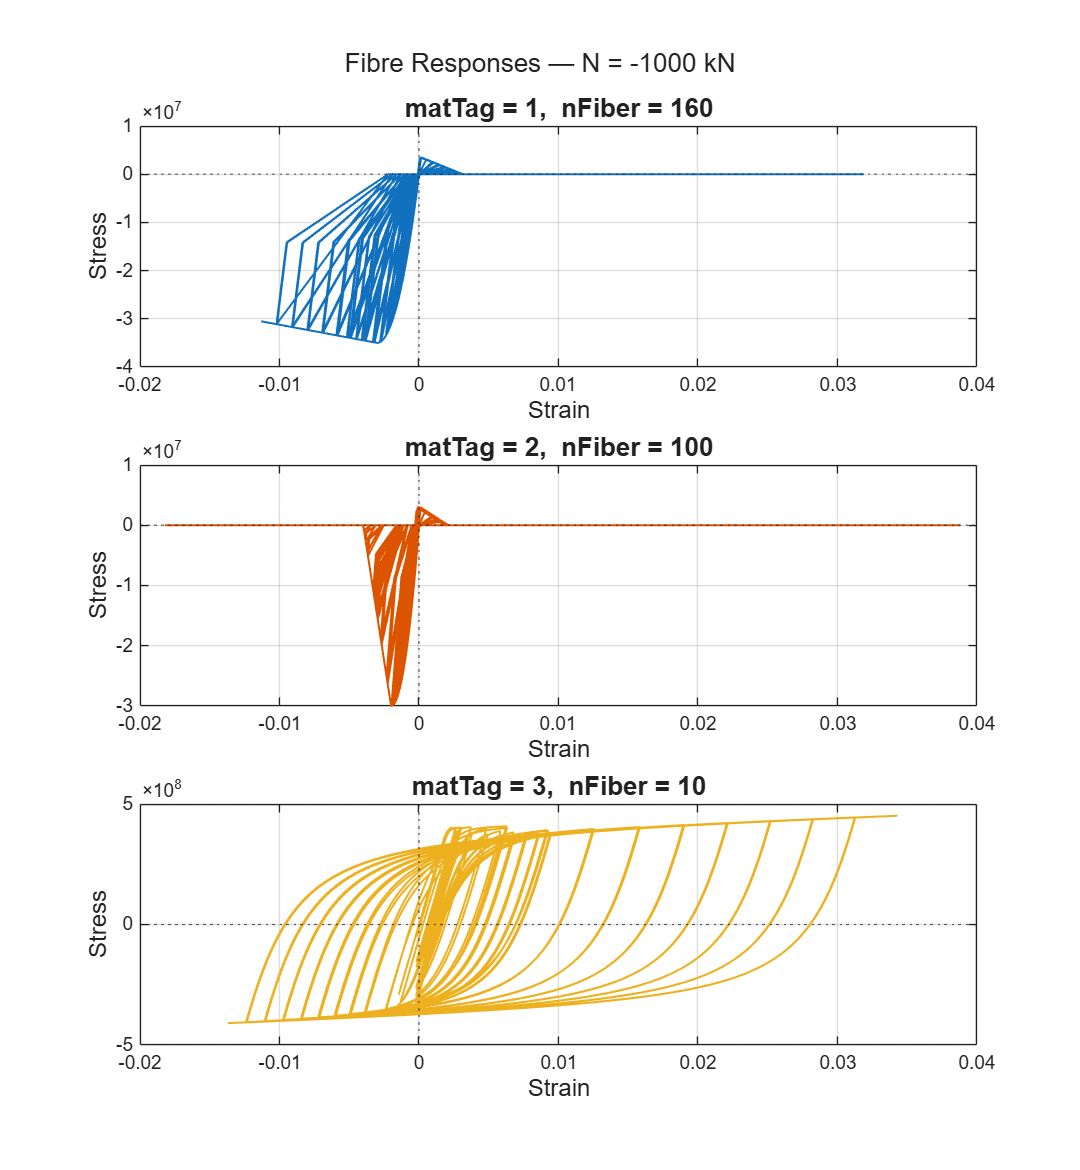

mc_cyc.plotFiberResponses();
sgtitle('Fibre Responses — N = -1000 kN', 'FontSize',13);